## 最小二乘问题求解

数据来自fred。读取的指标的参数缩写。 运用线性回归预测GDP变化，自变量包括失业率，工人工资和联邦基金率。

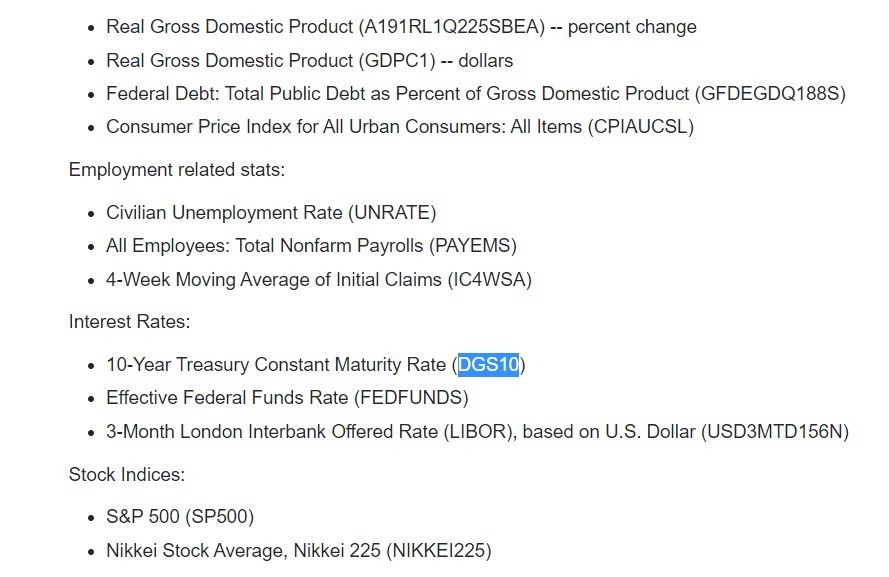


freddata = readtable('fred_data.csv');
data = freddata.Variables;
Temp = zscore(data);

Y = Temp(:,1);
X = Temp(:,2:end);
X_h = [X,ones(42,1)];
Beta = (X_h'*X_h)\X_h'*Y;
Pred_Y = X_h*Beta;
RMSE = sqrt(1/length(Y)*(Pred_Y-Y)'*(Pred_Y-Y));
RMSE = RMSE * std(data(:,1))  % 得到zscore前的变化

RMSE = 1.7375

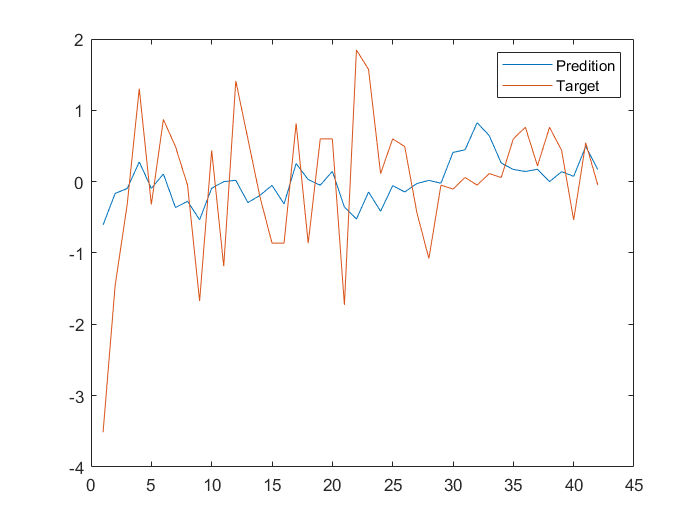

figure(1)
plot(Pred_Y);
hold on
plot(Y)
legend('Predition','Target')